# **Clustering of Income Inequality Data**

## **Read Data containing scaled indicators**

%% Import the data
[~, ~, raw] = xlsread('C:\Users\arsha_000\OneDrive\DS_Uni_15-16\Visual Analytics\Coursework2\mmscaled_group_country_merged.xlsx','Sheet1','C2:L215');

%% Create output variable
feat = reshape([raw{:}],size(raw));

%% Clear temporary variables
clearvars raw;

rng default  % For reproducibility

**Check input data dimensions**

size(feat)

ans =    214    10


## **Perform K-Means Clustering on the data with different k values and Cityblock distance**

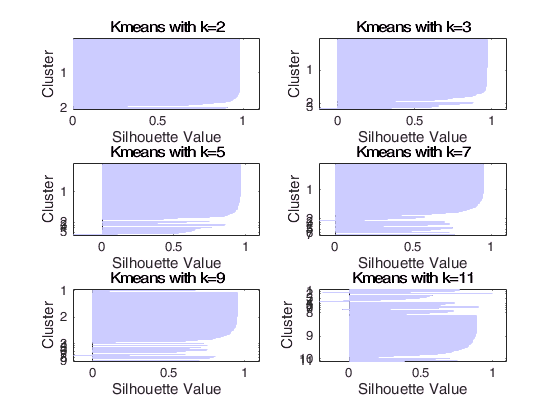

%Combined Figure
%%
figure
subplot(3,2,1)
%Kmeans with k=2
%%
%Cluster data
idx2 = kmeans(feat,2,'Distance','cityblock', 'Replicates',10);
%Plot Silhouette Value

[silh2, h] = silhouette(feat, idx2,'cityblock');
h =gca;
h.Children.EdgeColor = [0.8 0.8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'
title 'Kmeans with k=2'

subplot(3,2,2)
%Kmeans with k=3
%%
%Cluster data
idx3 = kmeans(feat,3,'Distance','cityblock', 'Replicates',10);
%Plot Silhouette Value

[silh3, h] = silhouette(feat, idx3,'cityblock');
h =gca;
h.Children.EdgeColor = [0.8 0.8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'
title 'Kmeans with k=3'

subplot(3,2,3)
%Kmeans with k=5
%%
%Cluster data
idx5 = kmeans(feat,5,'Distance','cityblock', 'Replicates',10);
%Plot Silhouette Value

[silh5, h] = silhouette(feat, idx5,'cityblock');
h =gca;
h.Children.EdgeColor = [0.8 0.8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'
title 'Kmeans with k=5'

subplot(3,2,4)
%Kmeans with k=7
%%
%Cluster data
idx7 = kmeans(feat,7,'Distance','cityblock', 'Replicates',10);
%Plot Silhouette Value

[silh7, h] = silhouette(feat, idx7,'cityblock');
h =gca;
h.Children.EdgeColor = [0.8 0.8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'
title 'Kmeans with k=7'

subplot(3,2,5)
%Kmeans with k=9
%%
%Cluster data
idx9 = kmeans(feat,9,'Distance','cityblock', 'Replicates',5);
%Plot Silhouette Value

[silh9, h] = silhouette(feat, idx9,'cityblock');
h =gca;
h.Children.EdgeColor = [0.8 0.8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'
title 'Kmeans with k=9'

subplot(3,2,6)
%Kmeans with k=11
%%
%Cluster data
idx11 = kmeans(feat,11,'Distance','cityblock', 'Replicates',5);
%Plot Silhouette Value

[silh11, h] = silhouette(feat, idx11,'cityblock');
h =gca;
h.Children.EdgeColor = [0.8 0.8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'
title 'Kmeans with k=11'

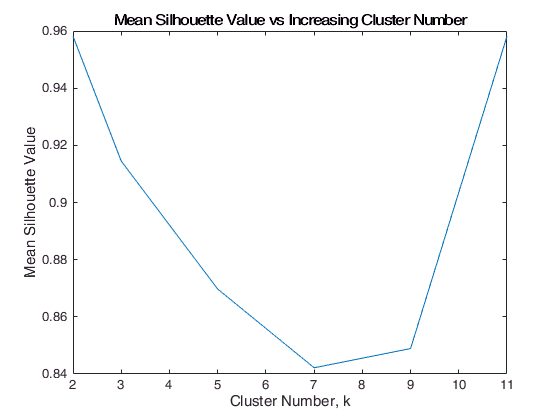

clust = [2,3,5,7,9,11];
sil_means = [mean(silh2), mean(silh3), mean(silh5), mean(silh7), mean(silh9), mean(silh2)];

figure
plot(clust, sil_means)
xlabel 'Cluster Number, k'
ylabel 'Mean Silhouette Value'
title 'Mean Silhouette Value vs Increasing Cluster Number'

# SOM Clustering

net5 = selforgmap([5 5]);
net10 = selforgmap([10 10]);
net15 = selforgmap([15 15]);

net5 = train(net5, feat);
net10 = train(net10, feat);
net15 = train(net15, feat);


## Plot of SOM Neighbour Weight Distances

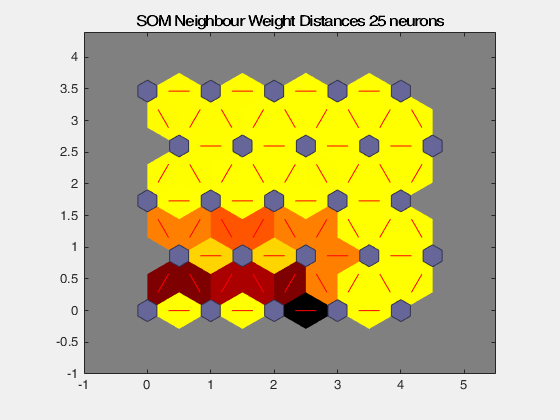

plotsomnd(net5)
title 'SOM Neighbour Weight Distances 25 neurons';

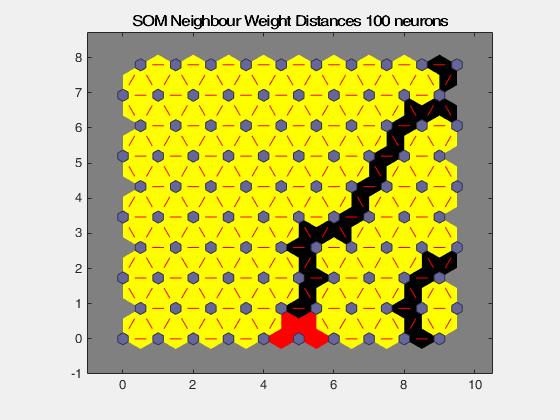


plotsomnd(net10)
title 'SOM Neighbour Weight Distances 100 neurons';

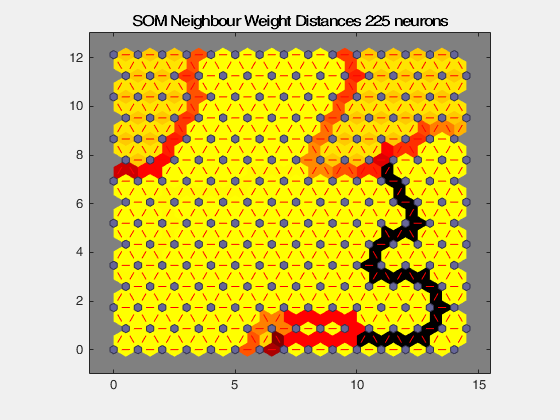


plotsomnd(net15)
title 'SOM Neighbour Weight Distances 225 neurons';

## Plot of SOM Hits

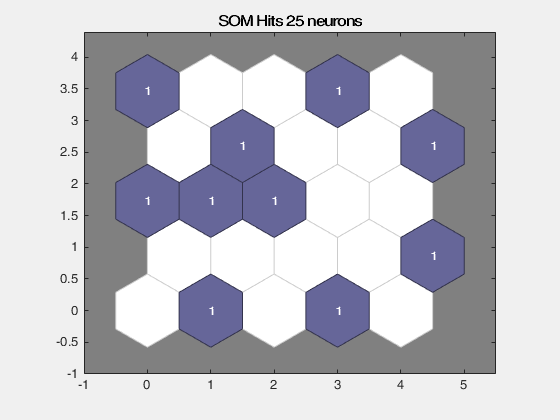

plotsomhits(net5,feat)
title 'SOM Hits 25 neurons';

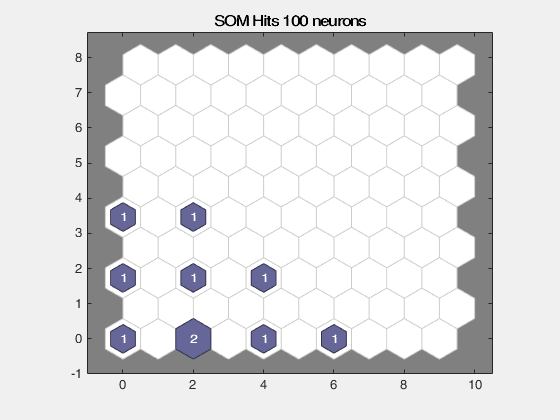


plotsomhits(net10,feat)
title 'SOM Hits 100 neurons';

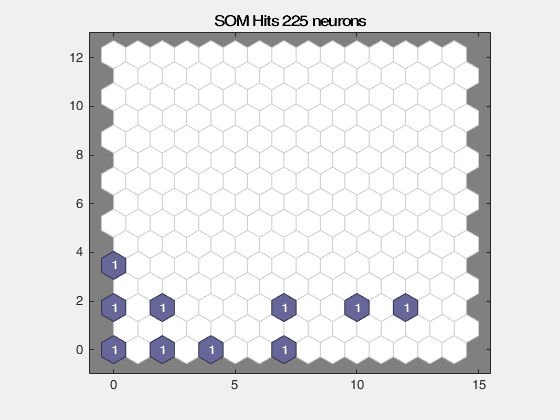


plotsomhits(net15,feat)
title 'SOM Hits 225 neurons';